# PRACTICA 4: Reducci´on de ruido en señales 1D

## Ejercicio 1

#### 1. Construir una señal de ruido blanco gausiano, usando ’randn’ .

N=1024; sigma=2;
s = sigma*randn(1,N);

#### 2. Calcular una transformada wavelet de distintos niveles y representar. Comparar los histogramas. Repetirlo con diferentes tipos de wavelets.

#### Haar

w = 'haar'

w = 'haar'

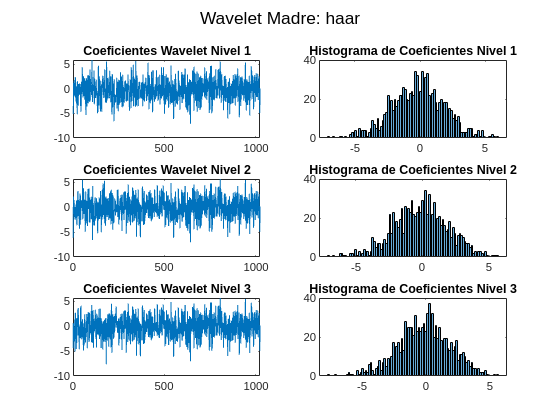

ans =    -4.4380    0.5314    0.2194   -0.7599   -1.2279   -3.1189   -1.7414   -0.8900   -1.5809    1.3397   -5.0774   -1.1837    2.6519    0.7749    0.3668   -0.5624   -0.7746   -4.5820    1.5526   -3.4583   -0.1621    0.6796    0.2247    1.4930    0.8642    3.3335   -1.9226    0.2798    3.6228    0.0772   -0.6668    0.3715   -1.5358   -4.6391   -0.3332   -0.0978   -0.2711   -1.3953   -1.8839   -2.4188    3.6483    1.1167    0.0871    4.0328   -2.6722    0.9374   -1.2694    0.4982    0.8421   -2.1263


wHist(s,w)

#### db2

w = 'db2'

w = 'db2'

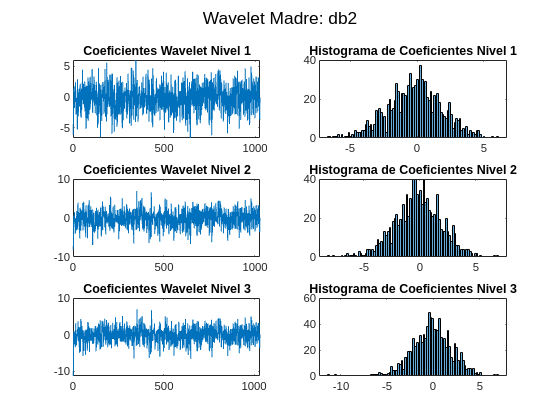

ans =   -11.3469  -10.5701   -0.1646    0.0339    0.8974   -2.0522   -2.1061   -2.0915   -2.7024   -0.8115    0.5788   -1.8358   -3.4863   -0.1726    3.1079    0.8222   -0.3258   -1.5188   -2.9474   -1.5039   -1.3032    0.1799   -0.3964   -0.2210    1.4471    1.2255   -0.3326    3.6272   -1.8593    1.3985    2.1165   -0.5436   -0.3390    0.7546   -3.0163   -4.9972    2.0129    0.1460   -1.7482   -0.0520   -4.7294    0.6532    4.2506   -1.1313    3.6925   -0.1074   -1.2343   -0.5082   -0.4041    2.3470


wHist(s,w)

db3

w = 'db3'

w = 'db3'

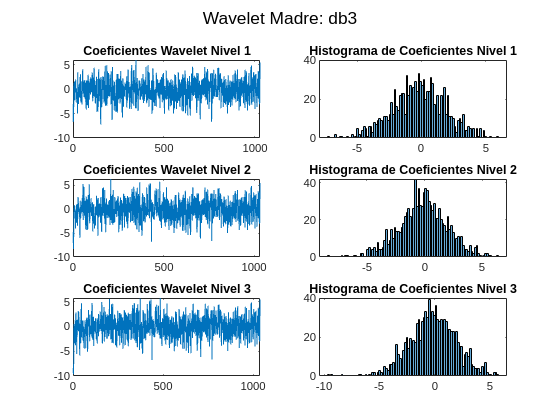

ans =    -8.3967   -9.2934   -9.6594   -5.1374    0.4891    0.1923   -0.2943   -1.6120   -3.3793   -1.5059   -1.5915   -1.3508    1.1913   -3.7920   -2.5741    2.7782    1.5266   -0.1402   -0.5640   -0.5467   -5.5419    1.3202   -1.5875   -0.3031   -0.7713    1.4390    0.8819    0.1119    3.0594   -0.3320   -0.9961    3.0024    1.0345   -0.8935    0.6417   -0.5987   -5.8835    0.3724   -0.3746    0.5761   -2.0983   -1.5214   -3.4151    3.4762    1.6816   -0.3862    4.6679   -2.2441   -1.0997    0.0454


wHist(s,w)

#### 3. Estimar la desviaci´on t´ıpica y comparar con el valor de sigma.

a) Calcular la desviaci´on t´ıpica (std) de la subseñal de fluctuaci´on d1.

b) Utilizar el estimador de Donoho: Mediana|(d1)i|/0,6745.

c) Utilizar el comando wnoisest.

w = 'db3'

w = 'db3'

[C, L] = wavedec(s, 1, w);

% Extraer la subseñal de fluctuación d1 del primer nivel
d1 = detcoef(C, L, 1);

% Ahora puedes seguir con las estimaciones de la desviación típica
% 1. Calcular la desviación típica de d1
std_d1 = std(d1);

% 2. Utilizar el estimador de Donoho
donoho_est = median(abs(d1)) / 0.6745;

% 3. Utilizar el comando wnoisest
sigma_est = wnoisest(C, L, 1);

% Comparar los valores estimados con el valor de sigma
fprintf('Desviación típica de d1: %f\n', std_d1);

Desviación típica de d1: 2.049147


fprintf('Estimador de Donoho: %f\n', donoho_est);

Estimador de Donoho: 2.045045


fprintf('Estimación de wnoisest: %f\n', sigma_est);

Estimación de wnoisest: 2.045045


fprintf('Valor de sigma: %f\n', sigma);

Valor de sigma: 2.000000


#### 4. Calcular los umbrales con el comando thselect y compararlos.

fprintf('--------------------')

--------------------

% Calcular el umbral utilizando thselect
thr_rigrsure = thselect(s, 'rigrsure'); % Umbral con la regla Rigrsure
thr_heursure = thselect(s, 'heursure'); % Umbral con la regla Heuristic Sure
thr_sqtwolog = thselect(s, 'sqtwolog'); % Umbral con la regla Square Root
thr_minimaxi = thselect(s, 'minimaxi'); % Umbral con la regla Minimax

% Comparar los umbrales calculados
fprintf('Umbral Rigrsure: %f\n', thr_rigrsure);

Umbral Rigrsure: 0.466094


fprintf('Umbral Heuristic Sure: %f\n', thr_heursure);

Umbral Heuristic Sure: 3.723297


fprintf('Umbral Square Root: %f\n', thr_sqtwolog);

Umbral Square Root: 3.723297


fprintf('Umbral Minimax: %f\n', thr_minimaxi);

Umbral Minimax: 2.222600


#### 5. Aplicar los diferentes umbrales (con wthresh o wthcoef) a la transformada, representar y observar el n´umero de coeficientes no nulos que sobreviven.

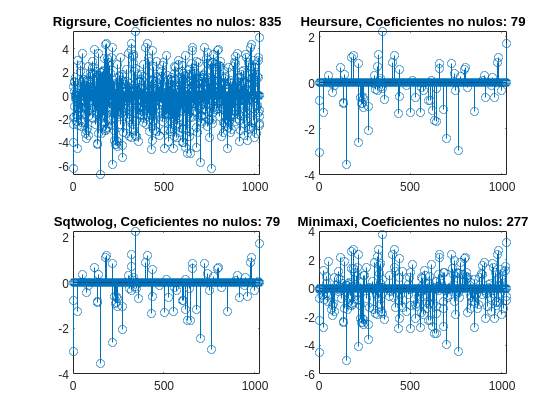

% Aplicar los umbrales y contar los coeficientes no nulos
C_rigrsure = wthresh(C, 's', thr_rigrsure);
C_heursure = wthresh(C, 's', thr_heursure);
C_sqtwolog = wthresh(C, 's', thr_sqtwolog);
C_minimaxi = wthresh(C, 's', thr_minimaxi);

% Contar los coeficientes no nulos
nnz_rigrsure = nnz(C_rigrsure);
nnz_heursure = nnz(C_heursure);
nnz_sqtwolog = nnz(C_sqtwolog);
nnz_minimaxi = nnz(C_minimaxi);

% Representar los resultados
figure;
subplot(2,2,1);
stem(C_rigrsure); title(['Rigrsure, Coeficientes no nulos: ' num2str(nnz_rigrsure)]);
subplot(2,2,2);
stem(C_heursure); title(['Heursure, Coeficientes no nulos: ' num2str(nnz_heursure)]);
subplot(2,2,3);
stem(C_sqtwolog); title(['Sqtwolog, Coeficientes no nulos: ' num2str(nnz_sqtwolog)]);
subplot(2,2,4);
stem(C_minimaxi); title(['Minimaxi, Coeficientes no nulos: ' num2str(nnz_minimaxi)]);

#### 7. Reconstruir la señal umbralizada y representarla.

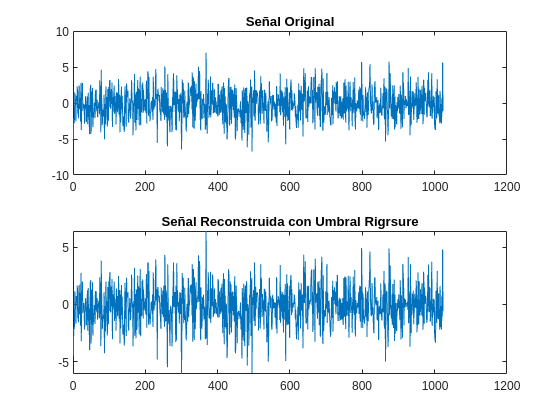

% Reconstruir la señal umbralizada
s_reconstruida = waverec(C_rigrsure, L, w);

% Representar la señal original y la señal umbralizada
figure;
subplot(2,1,1);
plot(s); title('Señal Original');
subplot(2,1,2);
plot(s_reconstruida); title('Señal Reconstruida con Umbral Rigrsure');

#### 8. Repertir para un ruido con distribuci´on uniforme, utilizando ’rand’.

clear
% 1. Construir una señal de ruido blanco gausiano, usando %randn  .
N=1024;
s = -1 + 2*rand(1,N);

%2. Calcular una transformada wavelet de distintos niveles y representar. Comparar los histogramas. Repetirlo con diferentes tipos de wavelets.
% Haar
w = 'haar'

w = 'haar'

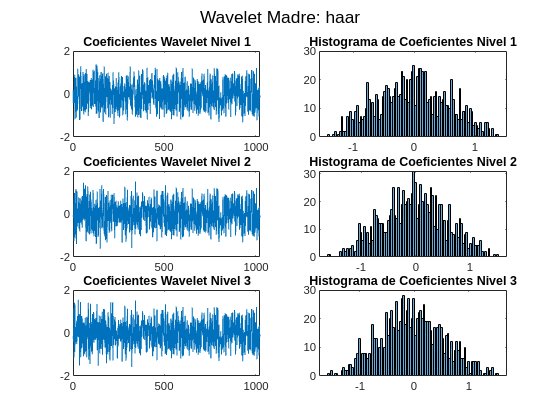

ans =    -0.1460   -0.2681   -0.4279    1.1369   -0.7486   -1.1532    0.4586    1.4070   -0.8770   -0.4494    1.3268   -0.5272   -0.1026    0.0095   -0.1779    0.2742   -0.4110   -0.1351   -0.1974    0.5606   -0.5083   -0.0448    0.5945    0.1035    0.7920   -0.1598   -0.0578    0.5411    1.5472   -0.0019   -0.1996    0.6772    0.0520    0.8814   -0.1111   -1.5153    0.8312   -0.7778    0.1938   -0.7509    1.4384   -1.1303    0.2055   -0.7487   -0.2349    0.7953    0.2055    0.7792   -0.6866    0.6917


wHist(s,w)

% db2
w = 'db2'

w = 'db2'

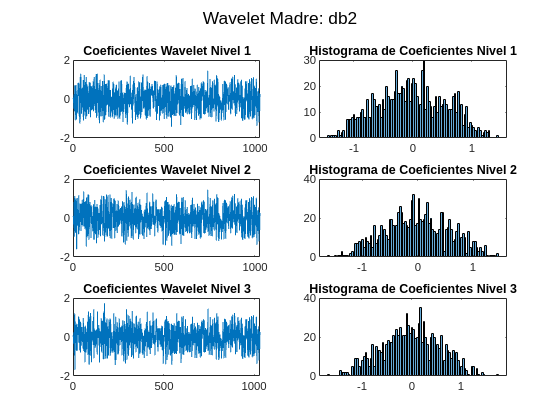

ans =     0.0797    0.0288   -0.3289    0.2392   -0.1997    0.1656   -0.6861   -0.9639    1.2040    0.9469   -1.6792    0.8106    0.5789   -0.2774   -0.1199   -0.1545    0.6010   -0.6870   -0.5426   -0.1149    0.6842    0.0622   -0.7105    0.5174    0.4892    0.1645    0.1109    0.0990    0.3375    0.8250    1.0460   -0.2978    0.6948   -0.1811    0.3281    0.9005   -0.6963   -0.4075   -0.0417   -0.0635   -0.8012    0.7823   -0.0939   -0.3937   -0.4369   -0.1789   -0.0810    0.4684    0.5036    0.5077


wHist(s,w)

% db3
w = 'db3'

w = 'db3'

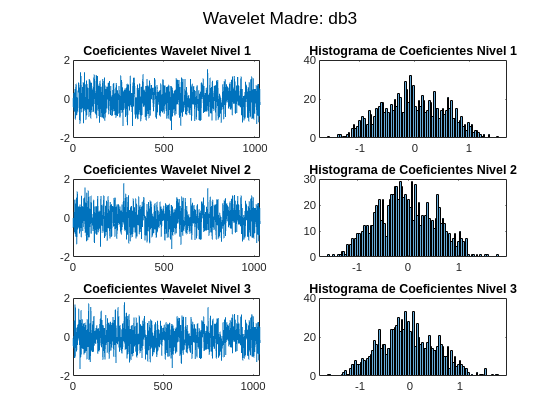

ans =    -0.4568   -0.0791   -0.4847   -0.2125    0.0455   -0.5907    0.8294   -0.5186   -1.0742   -0.0146    1.6605   -0.5895   -0.9856    1.5251   -0.3242   -0.1582    0.1562   -0.1840    0.2315   -0.7460   -0.1901    0.0316    0.5234   -0.1415   -0.4043    0.6163    0.0652    0.6555   -0.0865    0.0271    0.3895    1.4526    0.2553   -0.1841    0.8300   -0.4226    0.8840    0.5618   -1.6347    0.8424   -0.8071    0.2632   -1.0436    1.3656   -0.9468    0.1752   -0.5617   -0.3359    0.3573    0.4036


wHist(s,w)

% 3. Estimar la desviaci´on t´ıpica y comparar con el valor de sigma.
% a) Calcular la desviaci´on t´ıpica (std) de la subseñal de fluctuaci´on d1.
% b) Utilizar el estimador de Donoho: Mediana|(d1)i|/0,6745.
% c) Utilizar el comando wnoisest.
w = 'db3'

w = 'db3'

[C, L] = wavedec(s, 1, w);

% Extraer la subseñal de fluctuación d1 del primer nivel
d1 = detcoef(C, L, 1);

% Ahora puedes seguir con las estimaciones de la desviación típica
% 1. Calcular la desviación típica de d1
std_d1 = std(d1);

% 2. Utilizar el estimador de Donoho
donoho_est = median(abs(d1)) / 0.6745;

% 3. Utilizar el comando wnoisest
sigma_est = wnoisest(C, L, 1);

% Comparar los valores estimados con el valor de sigma
fprintf('Desviación típica de d1: %f\n', std_d1);

Desviación típica de d1: 0.564262


fprintf('Estimador de Donoho: %f\n', donoho_est);

Estimador de Donoho: 0.577459


fprintf('Estimación de wnoisest: %f\n', sigma_est);

Estimación de wnoisest: 0.577459


% 4. Calcular los umbrales con el comando thselect y compararlos.
fprintf('--------------------')

--------------------

% Calcular el umbral utilizando thselect
thr_rigrsure = thselect(s, 'rigrsure'); % Umbral con la regla Rigrsure
thr_heursure = thselect(s, 'heursure'); % Umbral con la regla Heuristic Sure
thr_sqtwolog = thselect(s, 'sqtwolog'); % Umbral con la regla Square Root
thr_minimaxi = thselect(s, 'minimaxi'); % Umbral con la regla Minimax

% Comparar los umbrales calculados
fprintf('Umbral Rigrsure: %f\n', thr_rigrsure);

Umbral Rigrsure: 0.999716


fprintf('Umbral Heuristic Sure: %f\n', thr_heursure);

Umbral Heuristic Sure: 3.723297


fprintf('Umbral Square Root: %f\n', thr_sqtwolog);

Umbral Square Root: 3.723297


fprintf('Umbral Minimax: %f\n', thr_minimaxi);

Umbral Minimax: 2.222600


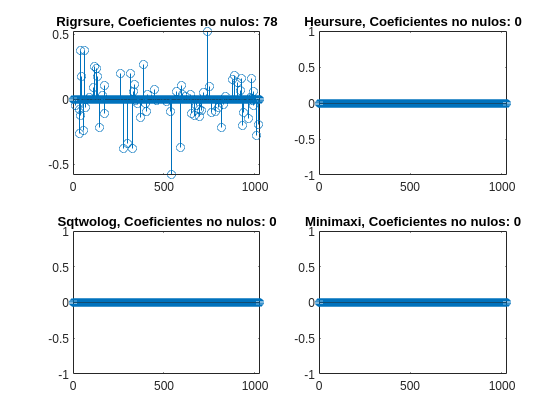

% 5. Aplicar los diferentes umbrales (con wthresh o wthcoef) a la transformada, representar y observar el n´umero de coeficientes no nulos que sobreviven.
% Aplicar los umbrales y contar los coeficientes no nulos
C_rigrsure = wthresh(C, 's', thr_rigrsure);
C_heursure = wthresh(C, 's', thr_heursure);
C_sqtwolog = wthresh(C, 's', thr_sqtwolog);
C_minimaxi = wthresh(C, 's', thr_minimaxi);

% Contar los coeficientes no nulos
nnz_rigrsure = nnz(C_rigrsure);
nnz_heursure = nnz(C_heursure);
nnz_sqtwolog = nnz(C_sqtwolog);
nnz_minimaxi = nnz(C_minimaxi);

% Representar los resultados
figure;
subplot(2,2,1);
stem(C_rigrsure); title(['Rigrsure, Coeficientes no nulos: ' num2str(nnz_rigrsure)]);
subplot(2,2,2);
stem(C_heursure); title(['Heursure, Coeficientes no nulos: ' num2str(nnz_heursure)]);
subplot(2,2,3);
stem(C_sqtwolog); title(['Sqtwolog, Coeficientes no nulos: ' num2str(nnz_sqtwolog)]);
subplot(2,2,4);
stem(C_minimaxi); title(['Minimaxi, Coeficientes no nulos: ' num2str(nnz_minimaxi)]);

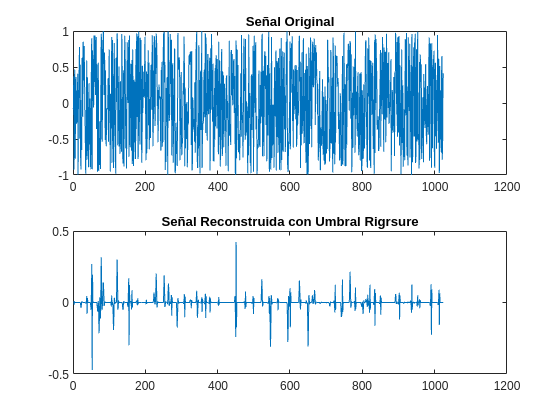


% 7. Reconstruir la señal umbralizada y representarla.
% Reconstruir la señal umbralizada
s_reconstruida = waverec(C_rigrsure, L, w);

% Representar la señal original y la señal umbralizada
figure;
subplot(2,1,1);
plot(s); title('Señal Original');
subplot(2,1,2);
plot(s_reconstruida); title('Señal Reconstruida con Umbral Rigrsure');

## Ejercicio 2

#### 1. Construir una señal de 2048 puntos en el intervalo [0,2] a partir de la funci´on


$$f(x) = 4x^2(1-x)^3(2-x)^2\cos(18x(1+x))$$


clear
% Definir el número de puntos y el intervalo
num_puntos = 2048;
x = linspace(0, 2, num_puntos); % Vector de puntos en el intervalo [0,2]

% Definir la función f(x)
fx = 4.*x.^2 .* (1-x).^3 .* (2-x).^2 .* cos(18.*x.*(1+x));

#### 2. Generar una señal ruidosa añadiendo ruido blanco gaussiano a la señal original. 

% Generar ruido blanco gaussiano
sigma = 0.05; % Puedes cambiar este valor para ajustar la varianza del ruido
ruido = sigma * randn(size(x));

% Añadir ruido a la señal original para obtener la señal ruidosa
senal_ruidosa = fx + ruido;

#### 3. Calcular la transformada de nivel n de la señal contaminada para una wavelet w. 

% Wavelet madre
w = 'db3';

% Definir el nivel de la descomposición
n = 5; % Cambiar este valor al nivel deseado

% Calcular la transformada wavelet de nivel n
[C, L] = wavedec(senal_ruidosa, n, w);

#### 4. Estimar la desviaci´on t´ıpica σ del ruido de la señal a partir de la fluctuaci´on de primer nivel o, bien, usar el comando wnoisest. 

% Extraer la fluctuación de primer nivel (detalle de primer nivel)
d1 = detcoef(C, L, 1);

% Estimar la desviación típica del ruido a partir de d1
% Método 1: Usar la desviación estándar de d1
sigma_est_d1 = std(d1);

% Método 2: Usar el estimador de Donoho
sigma_est_donoho = median(abs(d1)) / 0.6745;

% Método 3: Usar el comando wnoisest
sigma_est_wnoisest = wnoisest(C, L, 1);

% Mostrar los resultados
fprintf('Estimación σ de d1 (std): %f\n', sigma_est_d1);

Estimación σ de d1 (std): 0.051378


fprintf('Estimación σ con Donoho: %f\n', sigma_est_donoho);

Estimación σ con Donoho: 0.050873


fprintf('Estimación σ con wnoisest: %f\n', sigma_est_wnoisest);

Estimación σ con wnoisest: 0.050873


#### 5. Calcular un umbral, bien el umbral universal de Donoho: σ √ 2 log N o bien otros utilizando thselect, y aplicar dicho umbral a la transformada wavelet con wthresh o con wthcoef. 

% Calcular el umbral universal de Donoho
umbral_donoho = sigma * sqrt(2 * log(num_puntos));

% Calcular otros umbrales utilizando thselect
umbral_thselect = thselect(senal_ruidosa, 'rigrsure'); % Regla Rigrsure

% Aplicar el umbral universal de Donoho a la transformada wavelet
C_umbralizado_donoho = wthresh(C, 's', umbral_donoho);

% Aplicar el umbral de thselect a la transformada wavelet
C_umbralizado_thselect = wthresh(C, 's', umbral_thselect);

% Ahora puedes reconstruir la señal umbralizada y comparar
senal_reconstruida_donoho = waverec(C_umbralizado_donoho, L, w);
senal_reconstruida_thselect = waverec(C_umbralizado_thselect, L, w);

#### 6. Reconstruir la señal umbralizada. 

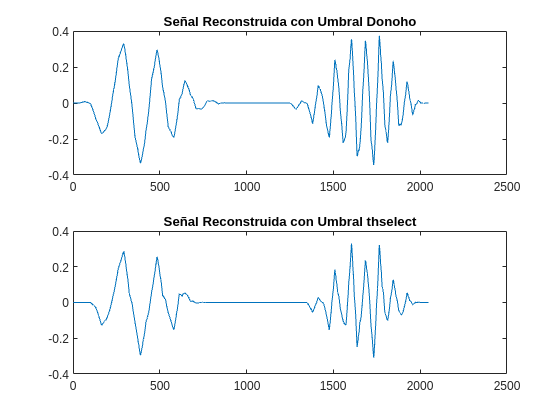

% Reconstruir la señal umbralizada con el umbral de Donoho
senal_reconstruida_donoho = waverec(C_umbralizado_donoho, L, w);

% Reconstruir la señal umbralizada con el umbral de thselect
senal_reconstruida_thselect = waverec(C_umbralizado_thselect, L, w);

% Visualizar las señales reconstruidas
figure;
subplot(2,1,1);
plot(senal_reconstruida_donoho); title('Señal Reconstruida con Umbral Donoho');
subplot(2,1,2);
plot(senal_reconstruida_thselect); title('Señal Reconstruida con Umbral thselect');

#### 7 Comparar la señal reconstru´ıda y la original.

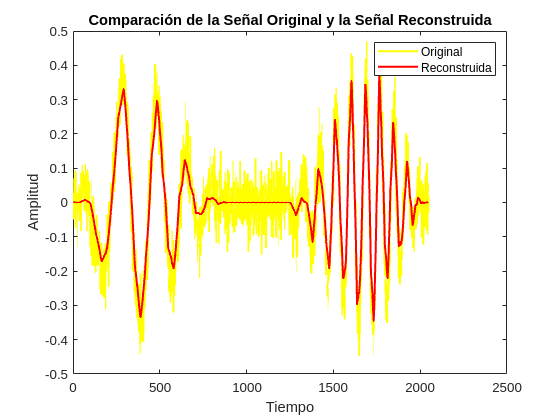

% Visualizar la señal original y la señal reconstruida en el mismo gráfico
figure;
plot(senal_ruidosa, 'y', 'LineWidth', 1.5); hold on; % Señal original en azul
plot(senal_reconstruida_donoho, 'r', 'LineWidth', 1.5); % Señal reconstruida en rojo
title('Comparación de la Señal Original y la Señal Reconstruida');
legend('Original', 'Reconstruida');
xlabel('Tiempo');
ylabel('Amplitud');
hold off;


% Calcular el Error Cuadrático Medio (MSE)
mse = immse(senal_ruidosa, senal_reconstruida_donoho);
fprintf('El Error Cuadrático Medio (MSE) entre la señal original y la reconstruida es: %f\n', mse);

El Error Cuadrático Medio (MSE) entre la señal original y la reconstruida es: 0.003685


## Ejercicio 3

#### Experimentar con el script del ejercicio para distintos niveles de ruido añadido (modificar el valor de sigma). 

#### Experimentar con diferentes tipos de wavelet y diferentes niveles de descomposici´on. Comparar los resultados. 

#### Experimentar con diferentes m´etodos de umbralizado: ‘hard’ y ‘soft threshold’. Comparar los resultados. 

#### Experimentar para diferentes señales, por ejemplo, cargar directamente: load noisbump, load noisdopp, load fdata. O bien, las pod´eis coger de los ejemplos de la APP Wavelet analyzer ’File => Example Analysis => Noisy Signals - Constant Noise Variance’

#### noisbump

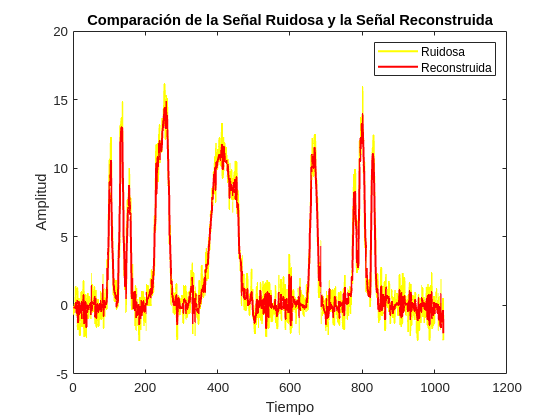

load noisbump; % Carga la señal 'noisbump'
[senal_reconstruida, mse] = analizarSenalRuidosa(noisbump, 'db3', 5, 's', 'rigrsure');

#### noisdopp

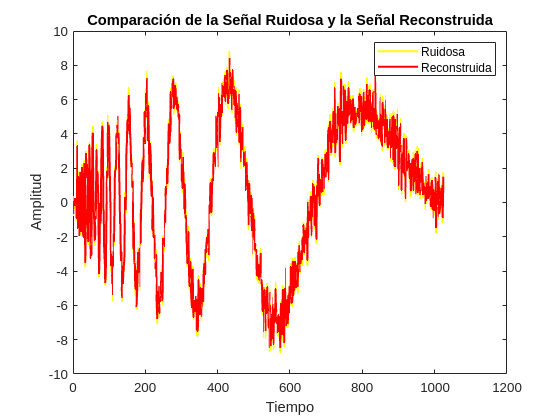

load noisdopp; % Carga la señal 'noisdopp'
[senal_reconstruida, mse] = analizarSenalRuidosa(noisdopp, 'db5', 5, 's', 'rigrsure');

#### fdata

% load fdata; % Carga la señal 'fdata'
% [senal_reconstruida, mse] = analizarSenalRuidosa(fdata, 'db4', 7, 'h', 'rigrsure');

## Ejercicio 5

% Ejemplo 1
clear
load noisdopp.mat;
s1 = noisdopp

s1 =     0.2958   -0.7214    0.2010   -0.3352   -0.0300   -0.0957   -0.0141    0.0630   -0.0097   -1.0498    0.3204    3.5609   -1.4369   -1.0694    0.6679    1.7343   -1.8502   -1.0642   -0.1377    1.8074   -0.3569   -1.9103   -1.2267   -0.8925    2.1957    0.0110   -0.8489   -1.8909   -2.0246   -0.0257    2.4194    1.4846   -1.5050   -3.7228   -2.0391    2.9531    2.0283    1.5651    2.4261   -1.3919   -1.4252   -2.4131    0.0615   -0.2556    3.4583    2.8573    1.3445   -1.1516   -3.2429   -2.3706


s1_den = wdenoise(s1)

s1_den =    -0.0973   -0.0986   -0.0995   -0.0988   -0.0973   -0.0955   -0.0932   -0.0907   -0.0881   -0.0850   -0.0818   -0.0790   -0.0763   -0.0735   -0.0663   -0.0693   -0.0796   -0.0198    0.0283    0.0092    0.0383   -0.3680   -0.9302   -0.0387    1.2337    0.5145   -0.6523   -0.5853   -0.3529    0.6768    1.9566    0.1564   -2.3259   -1.8588   -0.6327    0.7919    2.1741    1.7280    0.7420   -0.6367   -1.9689   -1.6423   -0.8468    0.8911    2.7097    2.0844    0.6920   -0.9914   -2.5697   -2.9854


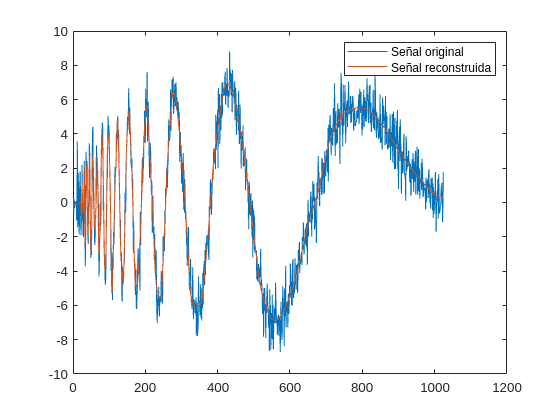


% Repreentamos la original y la reconstruida
figure; plot([s1' s1_den'])
legend('Señal original', 'Señal reconstruida')

## FUNCIONES

#### Ejercicio 1

function [C, L, fig] = wHist(s, w)
    % Inicialización de la figura
    fig = figure('Name', ['Wavelet Madre: ' w], ...
                 'NumberTitle', 'off');
    
    % Bucle para realizar la descomposición wavelet en niveles de 1 a 3
    for n = 1:3
        [C, L] = wavedec(s, n, w);
        
        % Subplot para los coeficientes wavelet
        subplot(3, 2, 2*n-1);
        plot(C);
        title(['Coeficientes Wavelet Nivel ' num2str(n)]);
        
        % Subplot para el histograma de coeficientes
        subplot(3, 2, 2*n);
        histogram(C, 100);
        title(['Histograma de Coeficientes Nivel ' num2str(n)]);
    end
    
    % Añadir un título general a la figura
    sgtitle(['Wavelet Madre: ' w]);
end

#### Ejercicio 3

function [senal_reconstruida, mse] = analizarSenalRuidosa(fx, w, n, tipo_umbral, metodo_umbral)
    % Asumir que 'fx' es la señal ruidosa proporcionada como entrada

    % Calcular la transformada wavelet de nivel n
    [C, L] = wavedec(fx, n, w);

    % Estimar la desviación típica del ruido usando wnoisest
    sigma_est = wnoisest(C, L, 1);

    % Calcular el umbral utilizando el método especificado
    umbral = thselect(fx, metodo_umbral);

    % Aplicar el umbral a la transformada wavelet
    C_umbralizado = wthresh(C, tipo_umbral, umbral);

    % Reconstruir la señal umbralizada
    senal_reconstruida = waverec(C_umbralizado, L, w);

    % Calcular el Error Cuadrático Medio (MSE) entre la señal original y la reconstruida
    % Asegúrate de tener la señal original sin ruido para calcular el MSE correctamente
    mse = immse(fx, senal_reconstruida);

    % Visualizar la señal ruidosa y la señal reconstruida en el mismo gráfico
    figure;
    plot(fx, 'y', 'LineWidth', 1.5); hold on; % Señal ruidosa en amarillo
    plot(senal_reconstruida, 'r', 'LineWidth', 1.5); % Señal reconstruida en rojo
    title('Comparación de la Señal Ruidosa y la Señal Reconstruida');
    legend('Ruidosa', 'Reconstruida');
    xlabel('Tiempo');
    ylabel('Amplitud');
    hold off;
end